# 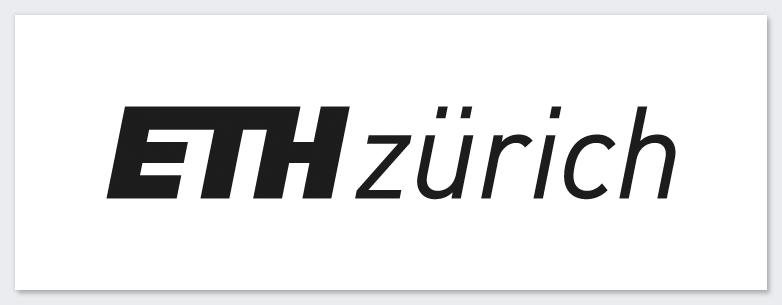

[**COMPUTATIONAL SCIENCE ZURICH**](http://www.zhcs.ch/)

[**Chair of Structural Mechanics**](http://www.chatzi.ibk.ethz.ch/)

[**Uncertainty Quantification & Data Analysis in Applied Sciences**](http://www.zhcs.ch/education/block-course/)

# MATLAB TUTORIAL - SYSTEM IDENTIFICATION

## 1. System Simulation

### 1.1 The system

The dynamical system considered in this tutorial pertains to a simple spring-mass-damper chain with two degrees of freedom (DOFs), shown in the following picture.

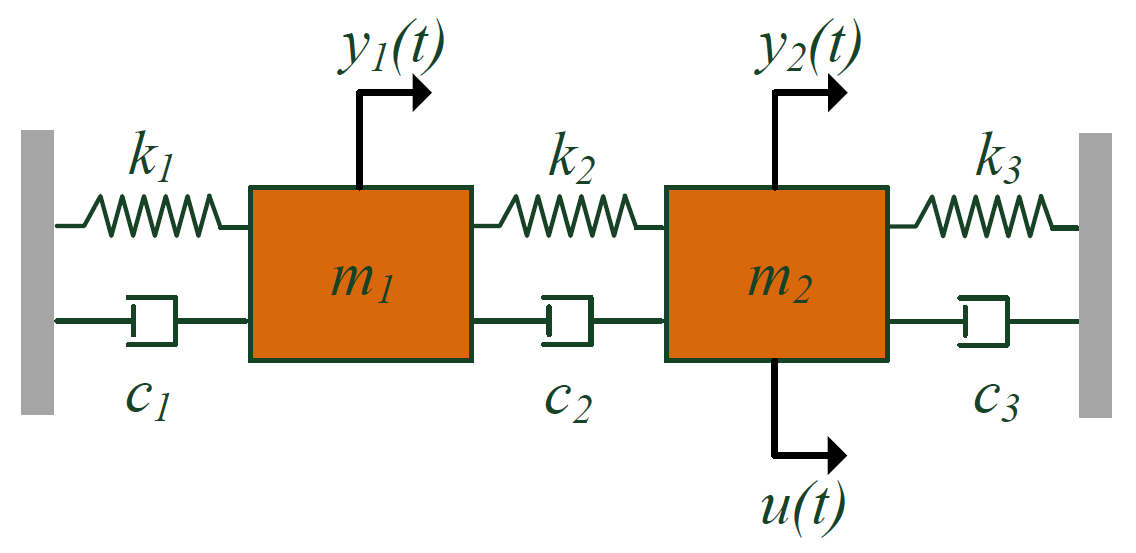

The equation of motion results from the application of Newton's second law to each DOF. It follows that the system is described by


$$\mathbf{M}\ddot{\mathbf{y}}(t)+\mathbf{C}\dot{\mathbf{y}}(t)+\mathbf{K}\mathbf{y}(t)=\mathbf{P}u(t)$$


where


$$\mathbf{M}=\pmatrix{m_1 & 0 \cr 0 & m_2},\quad
\mathbf{C}=\pmatrix{c_1+c_2 & -c_2 \cr -c_2 & c_2+c_3},\quad
\mathbf{K}=\pmatrix{k_1+k_2 & -k_2 \cr -k_2 & k_2+k_3},\quad
\mathbf{P}=\pmatrix{0 \cr 1},\quad
\mathbf{y}(t)=\pmatrix{y_1(t) \cr y_2(t)}$$


### 1.2 Create structural matrices in MATLAB

The following code creates the structural matrices in MATLAB. Observe that the damping matrix does not exactly follow the structure of the figure: it is constructed by assigning a specific damping ratio to each mode of vibration. This form of damping is referred to as **Rayleight damping**.

clear
close all
clc

% create structural matrices
n = 2;
m = [1.241 4.500];  % Kg
k = [900 300 500];  % N/m
M = diag(m);
K = [k(1)+k(2) -k(2);-k(2) k(2)+k(3)];
wn = sqrt(eig(M^(-1/2)*K*M^(-1/2)));
A = [ones(length(wn),1) wn.^2];
b = 2*wn.*[0.05;0.05];
x = A\b;
C = x(1)*M + x(2)*K;
P = [0;1];

### 1.3 Obtain an insight among different domains

Here we trasform the system into state-space and transfer function format for displacement and acceleration output. We also plot the frequency response function. 

Try to fill in the missing code blocks.

% displacement: state-space
Ac = [zeros(n) eye(n);-M\K -M\C];
Bc = [zeros(n,1);M\P];
Cc = [eye(n) zeros(n)];
Dc = 0;
sys_D_ss_c = ss(Ac,Bc,Cc,Dc);
disp(' ')
display(sys_D_ss_c)
% displacement: transfer function
sys_D_tf_c = tf(sys_D_ss_c);
disp(' ')
display(sys_D_tf_c)
% displacement: frequency response
figure(1)
sys_D_frf_c = bodeplot(sys_D_tf_c(1,1),'k',sys_D_tf_c(2,1),'r'); grid on 
setoptions(sys_D_frf_c,'FreqUnits','Hz','Xlim',[.1 25]);
legend('$u$ to $y_1$','$u$ to $y_2$','Interpreter','Latex')

% acceleration: state-space
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------
% acceleration: transfer function
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------
% acceleration: frequency response
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

### 1.4 Simulate

We continue with the simulation of the system. The input is a realization of a zero-mean Gaussian white noise process.

Try to fill in the missing code blocks.

% displacement
Fs = 50;                            % Hz
Ts = 1/Fs;                          % s
N  = 2^14;                          % data points 
t  = 0:Ts:Ts*(N-1);t = t.';         % time vector
uk = 10*randn(N,1);                 % input
sys_D_ss_d = c2d(sys_D_ss_c,Ts);    % discrete-time state-space
yk_D = lsim(sys_D_ss_d,uk,t);       % response
figure(3)
subplot(211)
plot(t,yk_D(:,1),'k'), axis tight
xlabel('$t$ (s)','Interpreter','latex')
ylabel('$y_1[t]$ (m)','Interpreter','latex')
subplot(212)
plot(t,yk_D(:,2),'k'), axis tight
xlabel('$t$ (s)','Interpreter','latex')
ylabel('$y_2[t]$ (m)','Interpreter',"latex")

% acceleration
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% Noise corrupt the output data
nsRatio = 0.05;
nk_D = repmat(nsRatio*std(yk_D),N,1).*randn(N,n);
yk_D_n = yk_D + nk_D;
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% store input-output data for further processing
save displacementData sys_D_ss_c sys_D_tf_c sys_D_ss_d t uk yk_D nk_D yk_D_n Fs N
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

## 2. Non–parametric Time–Series Analysis

### 2.1 Basic statistics

From this point forward, unless otherwise specified, we assume availabiliy of **only** output, or input-output data (including the sampling rate), depending on the case study considered.

The first step in data processing aims at removing the mean value from the associated time-series and then plotting the sample probability density function. This is accomplished in the following code.

Try to fill in the missing code blocks.

clear
close all
clc

% load acceleration data
load('accelerationData.mat','yk_A','uk','Fs','N')

% acceleration: mean value removal
inp = uk - mean(uk);
out = yk_A - repmat(mean(yk_A),N,1);

% acceleration: pdf estimation
figure(1)
subplot(311)
spdf(inp);
subplot(312)
spdf(out(:,1));
subplot(313)
spdf(out(:,2));

% load displacement data
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% displacement: mean value removal
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% displacement: pdf estimation
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------


### 2.2 Correlation analysis

Accordingly, we perform correlation analysis, in order to detect periodicities in the signals, as well as to obtain a rough estimate of the **time constants **of the system. In the analysis of random signals, the autocorrelation function plays the role of the impulse response.

Try to fill in the missing code blocks.

% acceleration: correlation analysis
figure(2)
moments([inp out],300);

% displacement: correlation analysis
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

### 2.3 Spectral analysis

Non-parametric estimation **always** includes the processing of the available signals in the frequency domain.

Try to fill in the missing code blocks.

% input signal: amplitude spectrum
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% acceleration signals: amplitude spectrum
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% input signals: power spectrum
figure(4)
subplot(311)
pwelch(inp,2048,1024,2048,Fs);
subplot(312)
pwelch(out(:,1),2048,1024,2048,Fs);
subplot(313)
pwelch(out(:,2),2048,1024,2048,Fs);

% spectral analysis: frequency response functions
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

## 3. Output–only Identification

### 3.1 AR modelling

We now proceed with a parametric modelling of our time-series. As a first step, we consider AR models. The code below uses the function `getAR` to estimate an AR model from a range of orders. Open the function, in order to obtain an insight on the estimation steps.

Try to fill in the missing code blocks.

clear
close all
clc

% load data
load('accelerationData.mat','yk_A','Fs','N')

% mean value removal
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% create estimation and validation sets
outE = out(1:floor(0.8*N),:); Ne = length(outE);
outV = out(Ne+1:end,:);       

% AR(n) estimation
arModel = getAR(outE(:,1),Fs,4:20);
figure
compare(outV(:,1),arModel,1);

### 3.2 ARMA modelling

A second option for the parametric modelling of time-series is to employ ARMA models. Function `getARMA `elaborates on this.

Try to fill in the missing code blocks.

% ARMA(n,n) estimation
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

## 4. Input–output Identification

### 4.1 ARX modelling

When input-output data is available, we can estimate parametrizations that include the measured input. ARX and ARMAX are the most widely used. 

Starting with the ARX model, try to fill in the missing code blocks (function `getARX`). 

clear
close all
clc

% load data
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% mean value removal
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% create estimation and validation sets
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% ARX(n,n,0) estimation
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

### 4.2 ARMAX modelling

Next, try to fill in the missing code blocks for the ARMAX case (function `getARMAX`).

clear
close all
clc

% load data
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% mean value removal
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% create estimation and validation sets
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------
 
% ARMAX(n,n,n,0) estimation
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

## 5. Vector Time–Series Analysis

In the previous section we perfromed parametric identification using single input-single output data pairs. Vector models allow for simultaneous processing of all available data. In what follows, we first perfrom non-parametric estimation of the covariance matrix of the output and then multi-variate time-series modelling using VAR (output-only) and VARX (input-output) models.

Try to fill in the missing code blocks  (functions `getVAR` and `getVARX`).

clear
close all
clc

% load data
load('accelerationData.mat','yk_A','uk','Fs','N')

% mean value removal
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% create estimation and validation sets
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% covariance matrix estimation
figure(1)
vscf(out,500);

% VAR(n) estimation
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% VARX(n,n,0) estimation
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

## 6. Subspace Identification

### 6.1 Ho-Kalman realization

We now turn our attention to the subspace identification methods. We start with Ho-Kalman's realization.

Try to fill in the missing code blocks.

% step 1: execute the code of Sections 1.2-1.3: get sys_D_ss_c and sys_A_ss_c

% step 2: get the impulse response of the two systems (use MATLAB's function impulse)

% build the block Hankel matrix of the output (use provided function blockHankel)

% apply svd, plot the singular values and decide on the order

% get extenden observability and controllability matrices

% estimate A, B, C and D

### 6.2 Autonomous systems

Using a process siomilar to the one of the previous section, we can identify matrices A & C using free response data.

Try to fill in the missing code blocks.

% step 1: execute the code of Sections 1.2-1.3: get sys_D_ss_c and sys_A_ss_c

% step 2: get the free response of the two systems (use MATLAB's function initial)

% build the block Hankel matrix of the output (use provided function blockHankel)

% apply svd, plot the singular values and decide on the order

% get extended observability matrix

% estimate A and C

### 6.3 The MOESP algorithm

Finally, we apply the MOESP algorithm for the subspace identification of our system using input-output records.

Try to fill in the missing code blocks.

clear
close all
clc

% load data
load('accelerationData.mat','yk_A','uk','Fs','N')

% mean value removal
%--------------------------------------------------------
% MISSING CODE BLOCK
%--------------------------------------------------------

% MOESP estimation
ssModel = getSS(out,inp,Fs,2:10);